# Dumbbell Laplacian program with Chebychev discretization

Computes the eigenvalues and eigenfunctions of the Laplace operator on a dumbbell graph with uniform and Chebychev discretizations.

## Set up the graph structure and coordinates of the problem

Use the template function to define the dumbbell quantum graph. By default, the discretization type is uniform but you can choose it to be Chebyshev. You can also set other properties such as the number of discretization points per edge.

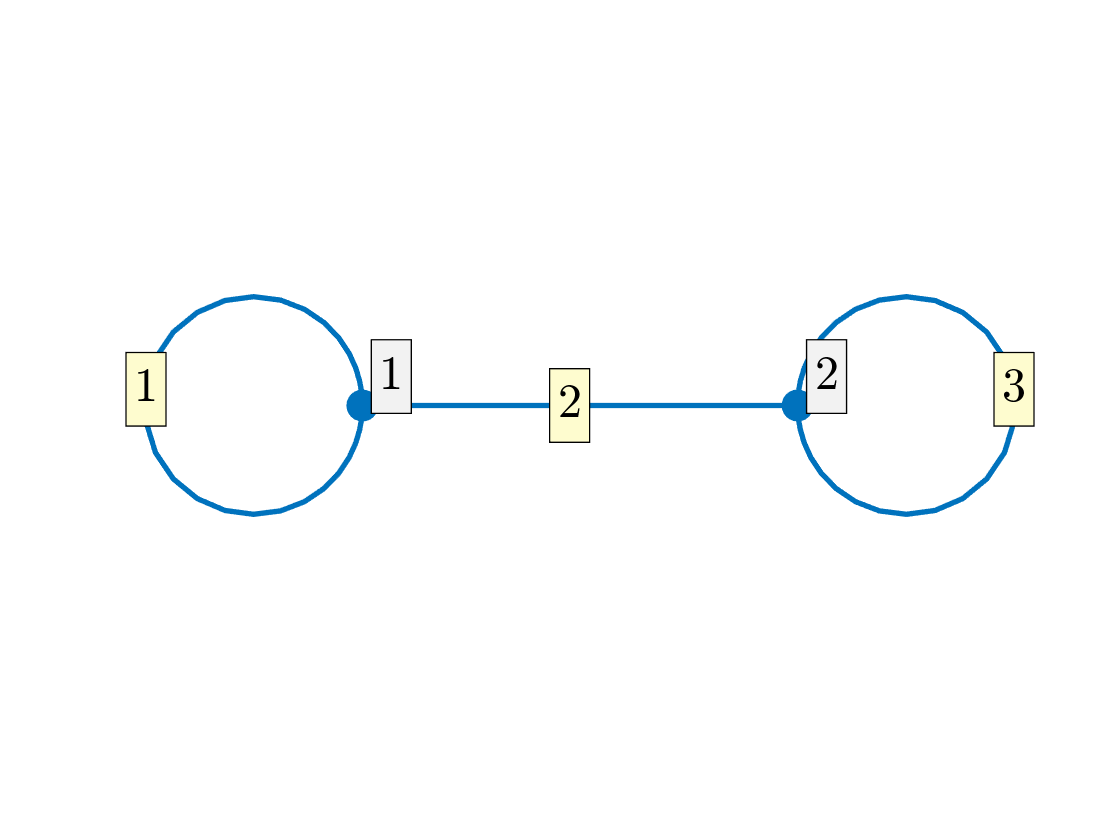

Phi = quantumGraphFromTemplate('dumbbell','discretization','Chebyshev','nX',32);
Phi.plot('layout')

The layout function is defined by the program `dumbbellPlotCoords` in the `templates` folder. 

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

Sometimes, the Laplacian matrix can be ill conditioned but our eigs function handles this. 

[V,lambda]=eigs(Phi,15);
[singles,doubles,~]=separateEigs(lambda); % No triple eigenvalue unless handle and hoops resonant
nToPlot=4;

## Plot the first few multiplicity-one eigenfunctions

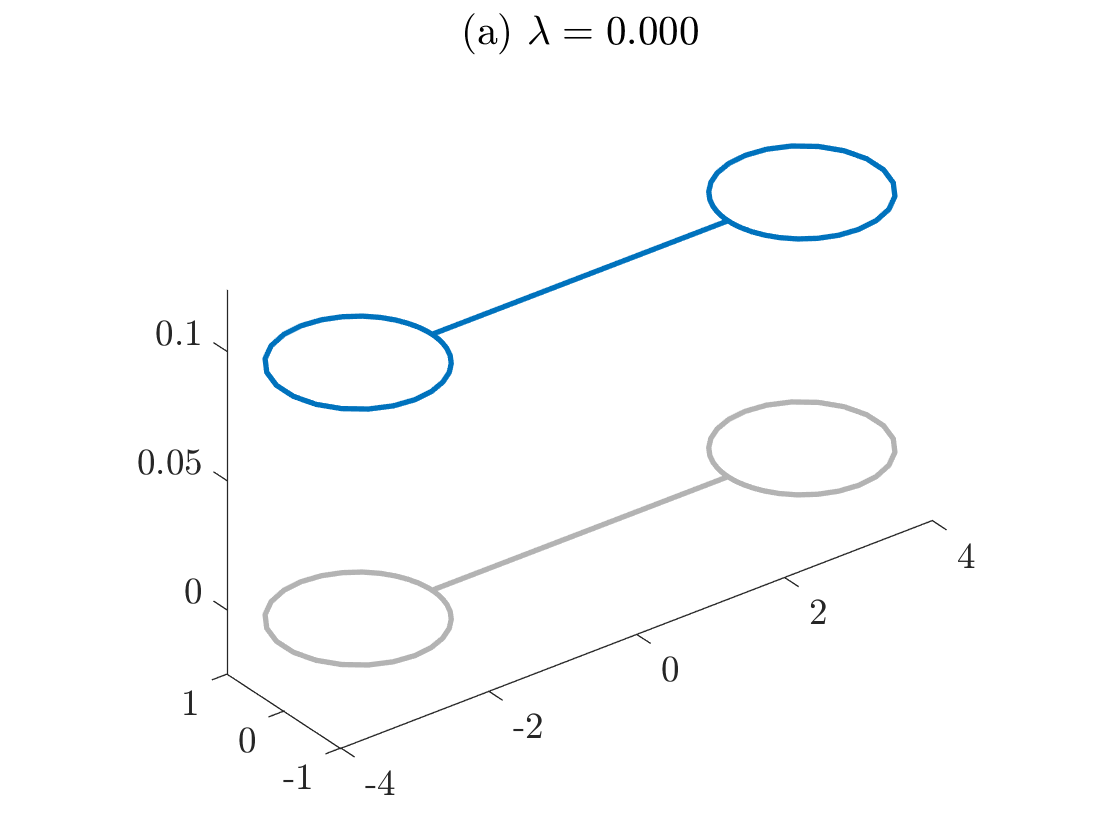

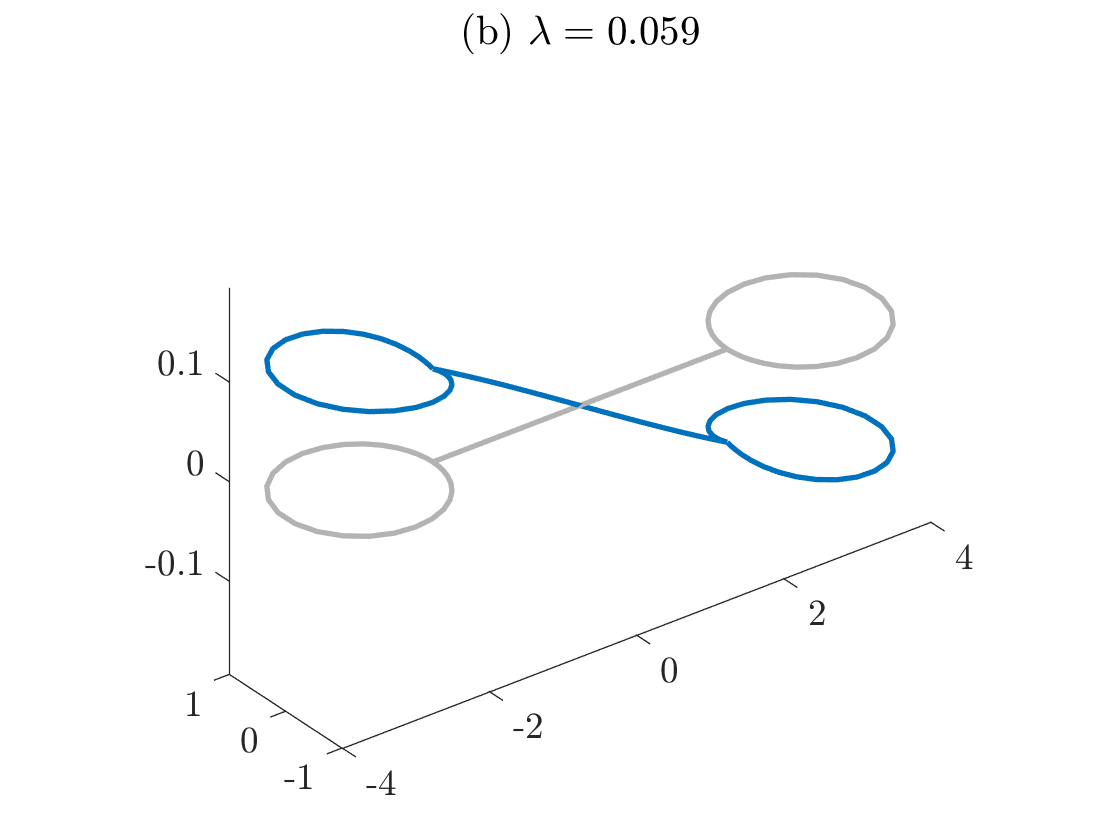

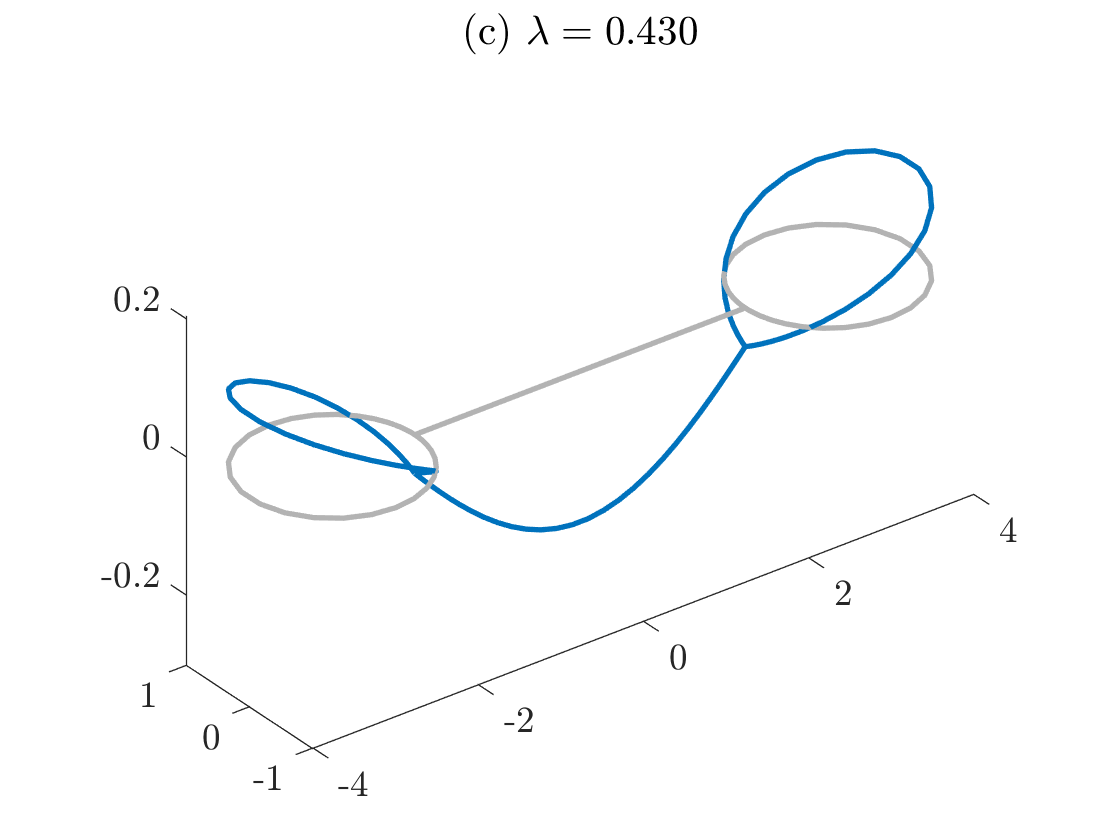

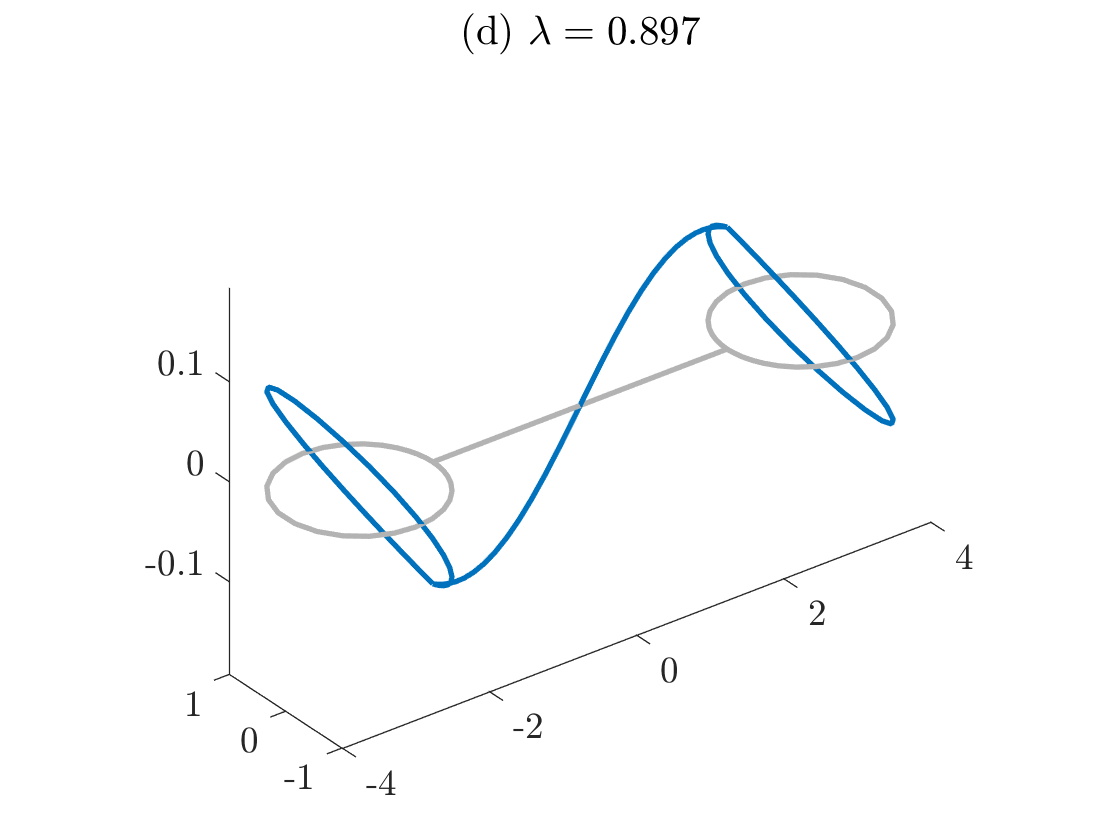

for k=1:nToPlot
    figure
    Phi.plot(V(:,singles(k)))
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(k),lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

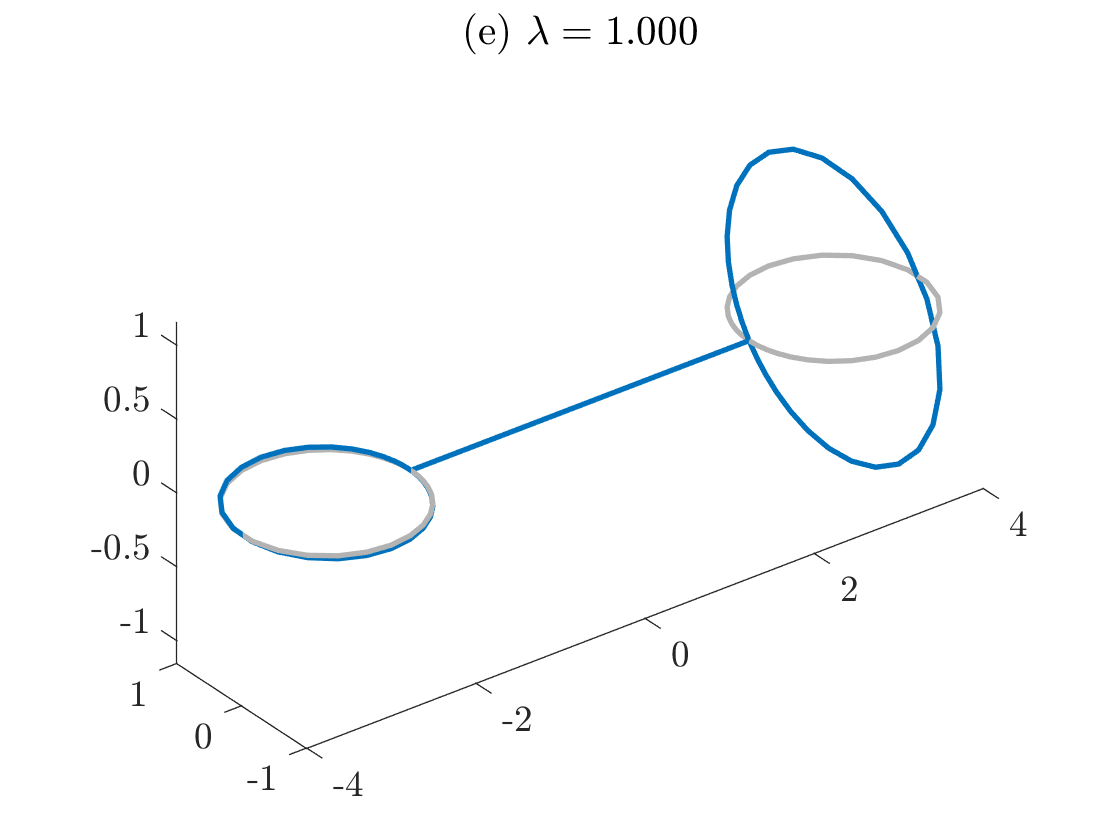

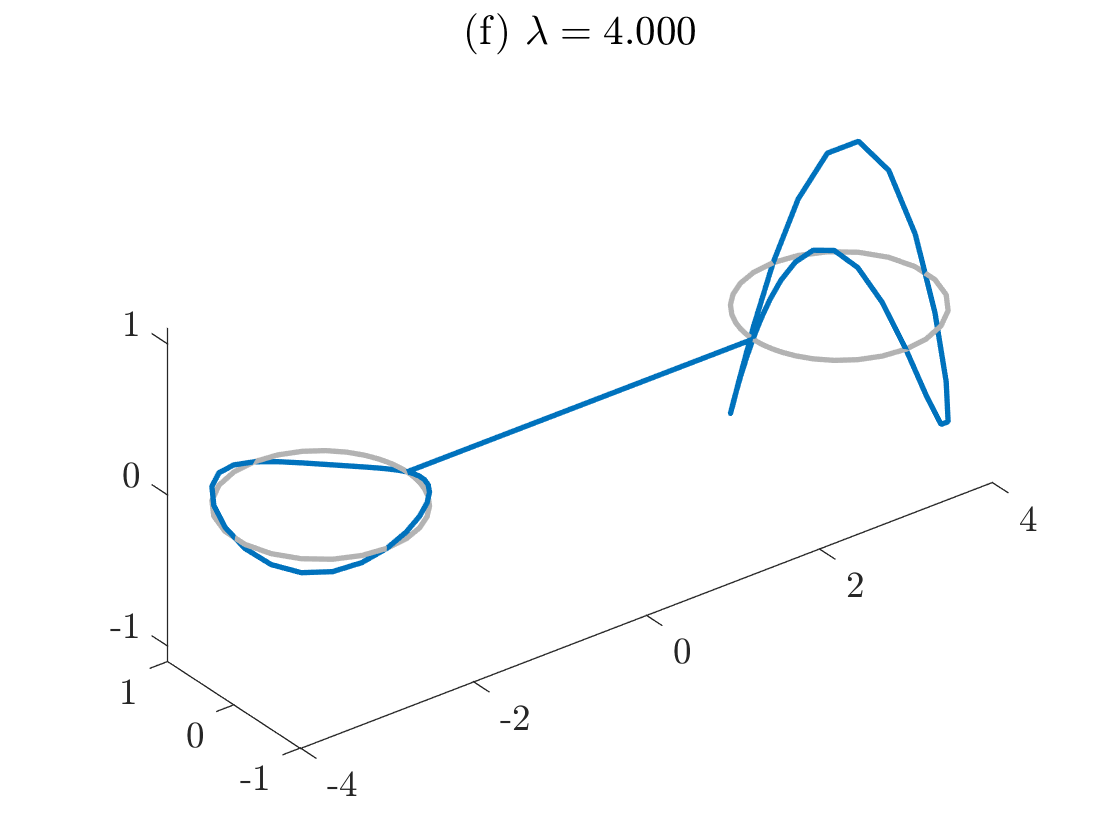

for k=1:nToPlot/2
    figure
    v=dumbbellResolveDoubles(V,doubles(k),Phi);
    Phi.plot(v{1})
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+k), lambda(doubles(k))));
end